s = tf('s');
G_theta = 0.067/(s^2 - 3.92)

G_theta =
 
    0.067
  ----------
  s^2 - 3.92
 
Continuous-time transfer function.



G_star = 14.93*(s^2-3.27)/s^2

G_star =
 
  14.93 s^2 - 48.82
  -----------------
         s^2
 
Continuous-time transfer function.



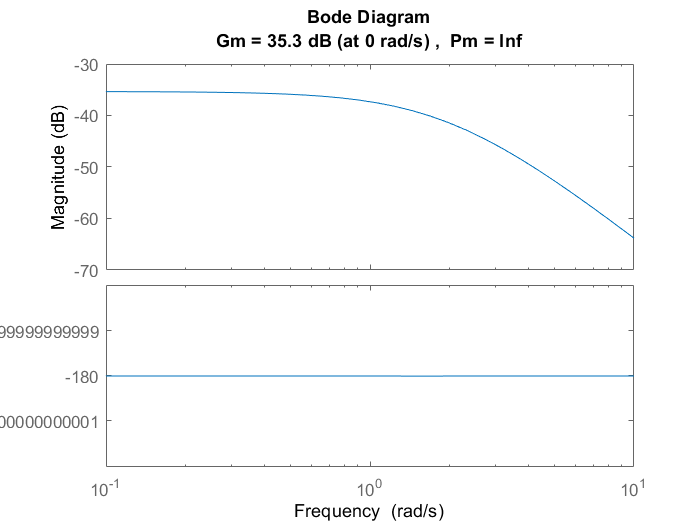

margin(G_theta)

[mag,phase,wout,sdmag,sdphase] = bode(G_theta,100)

mag = 6.6974e-06

phase = -180

wout = 100


sdmag =

     []


sdphase =

     []



K = lead(40,100)

K =
 
  s + 46.63
  ---------
  s + 214.5
 
Continuous-time transfer function.



L = K*G_theta

L =
 
          0.067 s + 3.124
  --------------------------------
  s^3 + 214.5 s^2 - 3.92 s - 840.6
 
Continuous-time transfer function.



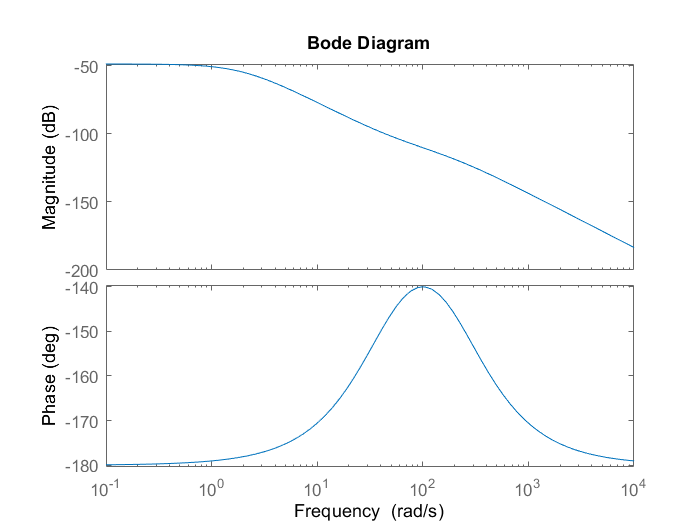

bode(L)

[mag,phase,wout,sdmag,sdphase] = bode(L,100)

mag = 3.1230e-06

phase = -140

wout = 100


sdmag =

     []


sdphase =

     []



L = L/mag

L =
 
                     0.067 s + 3.124
  ------------------------------------------------------
  3.123e-06 s^3 + 0.0006697 s^2 - 1.224e-05 s - 0.002625
 
Continuous-time transfer function.



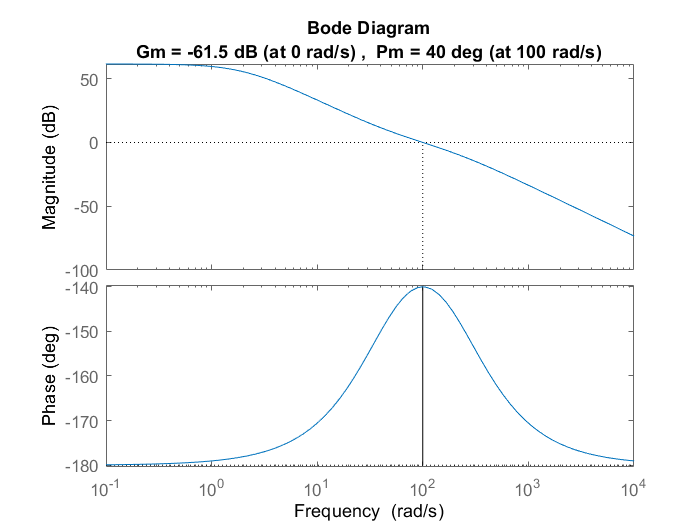

margin(L)

The negative Gain margin here signifies that how much gain can be reduced for the system to remain stable. It can also be explained in terms of the number of encirclements in the Nyquist diagram. Negative margin indicates that the amount of gain that can be reduced to ensure that the number of encirclements would not change to make the system unstable. This means that the system is currently giving high gain values than what we can use to ensure stability.

% Close the inner-loop
GG = feedback(L,1)

GG =
 
                   0.067 s + 3.124
  -------------------------------------------------
  3.123e-06 s^3 + 0.0006697 s^2 + 0.06699 s + 3.122
 
Continuous-time transfer function.



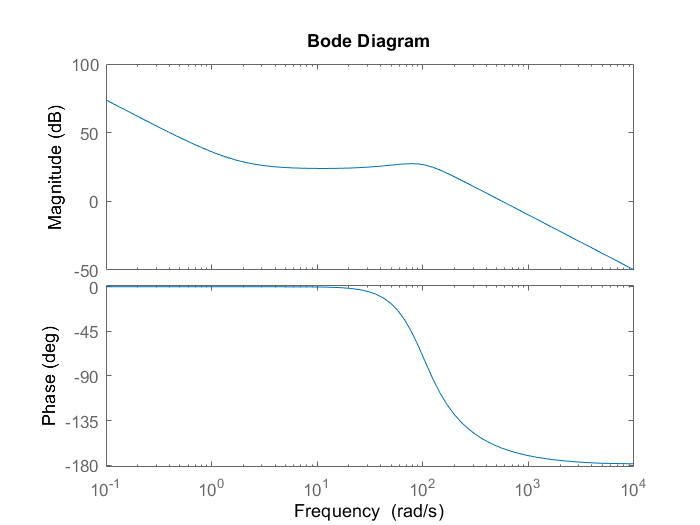

% Plot the bode plot of the plant 
P = GG*G_star;
bode(P)

wc = 2;
GAM = 3;

%loopsyn loop
while(GAM>2)
    [K,CL,GAM] = loopsyn(P,wc/s);
    wc = wc-0.01;
end

% Optimal crossover frequency
wc = wc + 0.01

wc = 0.8300

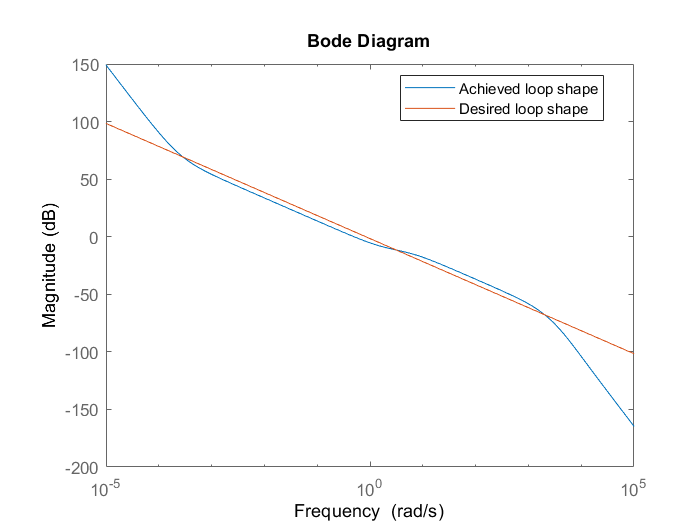

bodemag(K*P,wc/s)
legend('Achieved loop shape',"Desired loop shape","Location","best")